# `MATH 3620 Numerical Analysis`

# `Homework 8`

# `09 April 2021`

close all; clear all ; clc;

## `Q1. Boundary Value Problem - Finite Differences`

## `1a`

`The BVP is given by`


$$-u''(x) + \pi^2 u(x) = 2\pi^2sin(\pi x); u(0) = u(1) = 0$$


`Substitute `$u(x) = \sin(\pi x)$`. We get`


$$- (-\pi^2 \sin(\pi x)) + \pi^2 \sin(\pi x) = 2 \pi^2 \sin(\pi x)$$



$$2 \pi^2 \sin(\pi x) = 2 \pi^2 \sin(\pi x)$$


`Since the lhs equals the rhs of the equation, we have verified that `$u(x) = \sin(\pi x)$ `is a solution to the BVP.`

## `1b`

% parameters
a = 0; b16 = 1;
N = 50; h = (b16-a)/N;

% domain
x = a:h:b16;

% setup A and b
A16 = zeros(N-1, N+1);
b16 = 2*(pi^2)*sin(pi*x(2:end-1));
v1 = 0; vN = 0;
for i = 2:N 
    A16(i-1, i-1) = -1/(h^2);
    A16(i-1, i) = (pi^2) + 2/(h^2);
    A16(i-1, i+1) = A16(i-1, i-1);
end
b16 = b16' - v1*A16(:, 1) - vN*A16(:, end);

% solve for v
A16 = A16(:, 2:N);
v50 = tridiagsolver(A16, b16);
v50 = [v1; v50; vN];
% plot solution
plot(x, v50, 'r-', 'LineWidth', 2);
xlabel('x')
ylabel('v(x) \approx u(x)')
titlestring = ['Solutions to BVP, N = ', num2str(N)]

titlestring = 'Solutions to BVP, N = 50'

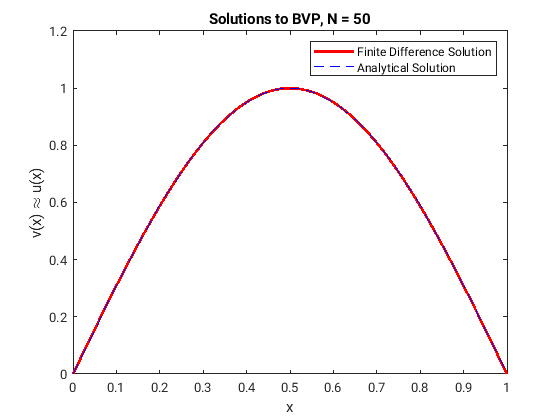

title(titlestring)
hold on
plot(x, sin(pi*x), 'b--')
legend('Finite Difference Solution', 'Analytical Solution')
hold off

% error
e50 = (sin(pi*x))' - v50;
fprintf('N = %d, 2-norm error = %g', N, norm(e50, 2))

N = 50, 2-norm error = 0.000822494

## `1c`

% parameters
a = 0; b16 = 1;
N = 100; h = (b16-a)/N;

% domain
x = a:h:b16;

% setup A and b
A16 = zeros(N-1, N+1);
b16 = 2*(pi^2)*sin(pi*x(2:end-1));
v1 = 0; vN = 0;
for i = 2:N 
    A16(i-1, i-1) = -1/(h^2);
    A16(i-1, i) = (pi^2) + 2/(h^2);
    A16(i-1, i+1) = A16(i-1, i-1);
end
b16 = b16' - v1*A16(:, 1) - vN*A16(:, end);

% solve for v
A16 = A16(:, 2:N);
v100 = tridiagsolver(A16, b16);
v100 = [v1; v100; vN];
% plot solution
plot(x, v100, 'r-', 'LineWidth', 2);
xlabel('x')
ylabel('v(x) \approx u(x)')
titlestring = ['Solutions to BVP, N = ', num2str(N)]

titlestring = 'Solutions to BVP, N = 100'

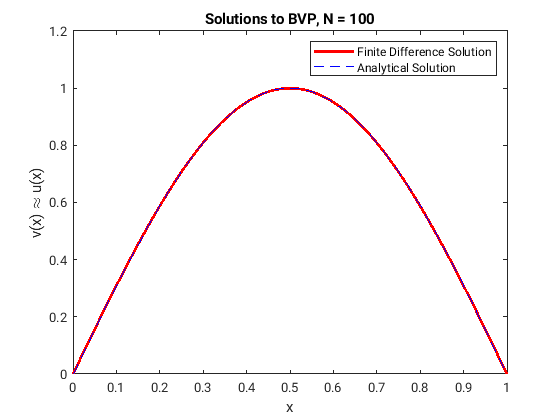

title(titlestring)
hold on
plot(x, sin(pi*x), 'b--')
legend('Finite Difference Solution', 'Analytical Solution')
hold off

% error
e100 = (sin(pi*x))' - v100;
fprintf('N = %d, 2-norm error = %g', N, norm(e100, 2))

N = 100, 2-norm error = 0.000290788

`The centered difference derivative approximation is "second-order accurate". Hence, doubling N is expected to reduce the error to 1/4th of the initial error. The initial error (N = 50) is 8.22e-4 and the error after doubling N is 2.90e-4, which is 0.35 (expected = 0.25) of the initial error.`

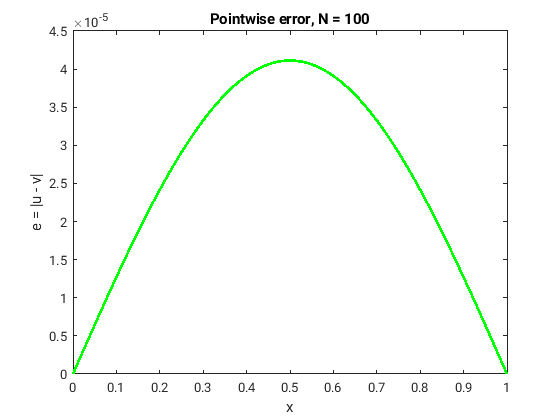

% plot point-wise error
plot(x, abs(e100), 'g-', 'LineWidth', 2)
title('Pointwise error, N = 100')
xlabel('x')
ylabel('e = |u - v|')

## `1d`

`When the exact solution is not known, the convergence can be checked by examining the quantity `$\left| v_{i+1} - v_{i}\right|$`(`$v_i = 
$ `solution with `$h = h_i$`)which should asymptotically approach 0 for a convergent solution and the rate of convergence is the slope of graph between `$log(h)$ `and `$log \left(\left| {v_{i+1} - v_i} \right| \right)$`.`

% rate of convergence using actual solution
h = [1/50 1/100];
e = [norm(e50, 2), norm(e100, 2)]; 
actual_roc = (log(e(2)) - log(e(1)))/(log(h(2)) - log(h(1)));
% approx rate of convergence 
% solution with N = 200
% parameters
a = 0; b16 = 1;
N = 200; h = (b16-a)/N;

% domain
x = a:h:b16;

% setup A and b
A16 = zeros(N-1, N+1);
b16 = 2*(pi^2)*sin(pi*x(2:end-1));
v1 = 0; vN = 0;
for i = 2:N 
    A16(i-1, i-1) = -1/(h^2);
    A16(i-1, i) = (pi^2) + 2/(h^2);
    A16(i-1, i+1) = A16(i-1, i-1);
end
b16 = b16' - v1*A16(:, 1) - vN*A16(:, end);

% solve for v
A16 = A16(:, 2:N);
v200 = tridiagsolver(A16, b16);
v200 = [v1; v200; vN];

% rate of convergence
h = [1/100, 1/200];
e = [norm(v100(51) - v50(26), 2), norm(v200(101) - v100(51), 2)]; % at center
approx_roc = (log(e(2)) - log(e(1)))/(log(h(2)) - log(h(1)));

% print results
fprintf('Rate of convergence using exact solution = %g', actual_roc)

Rate of convergence using exact solution = 1.50004

fprintf('Rate of convergence using approx. solution = %g', approx_roc)

Rate of convergence using approx. solution = 2.00004

## `2 - Solution Setup (N = 16, 32, 64 | tol = 1e-6)`

% N = 16
% parameters
a = 0; b = 1;
N = 16; h = (b-a)/N;

% domain
x16 = a:h:b;

% setup A and b
A16 = zeros(N-1, N+1);
b16 = 2*(pi^2)*sin(pi*x16(2:end-1));
v1 = 0; vN = 0;
for i = 2:N 
    A16(i-1, i-1) = -1/(h^2);
    A16(i-1, i) = (pi^2) + 2/(h^2);
    A16(i-1, i+1) = A16(i-1, i-1);
end
b16 = b16' - v1*A16(:, 1) - vN*A16(:, end);
A16 = A16(:, 2:N);

% N = 32
% parameters
a = 0; b = 1;
N = 32; h = (b-a)/N;

% domain
x32 = a:h:b;

% setup A and b
A32 = zeros(N-1, N+1);
b32 = 2*(pi^2)*sin(pi*x32(2:end-1));
v1 = 0; vN = 0;
for i = 2:N 
    A32(i-1, i-1) = -1/(h^2);
    A32(i-1, i) = (pi^2) + 2/(h^2);
    A32(i-1, i+1) = A32(i-1, i-1);
end
b32 = b32' - v1*A32(:, 1) - vN*A32(:, end);
A32 = A32(:, 2:N);

% N = 64
% parameters
a = 0; b = 1;
N = 64; h = (b-a)/N;

% domain
x64 = a:h:b;

% setup A and b
A64 = zeros(N-1, N+1);
b64 = 2*(pi^2)*sin(pi*x64(2:end-1));
v1 = 0; vN = 0;
for i = 2:N 
    A64(i-1, i-1) = -1/(h^2);
    A64(i-1, i) = (pi^2) + 2/(h^2);
    A64(i-1, i+1) = A64(i-1, i-1);
end
b64 = b64' - v1*A64(:, 1) - vN*A64(:, end);
A64 = A64(:, 2:N);

tol = 1e-6; % tolerance

## `Jacobi method`

% % test data (Example 1)
% % exact sol = [1, 2, -1, 1]
% A = [10 -1 2 0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8];
% b = [6; 25; -11; 15];
% n = size(b, 1);
% v = zeros(size(b));
% while (true)
%     vnew = zeros(size(v));
%     for i = 1:n
%         s = 0;
%         for j = 1:n
%             if (i ~= j)
%               s = s + A(i, j)*v(j);
%             end
%         end
%         vnew(i) = -(s - b(i))/A(i,i);
%     end
%     e = norm(vnew - v, 2)/norm(vnew, 2);
%     if e <= tol
%         v = vnew;
%         break;
%     end
%     v = vnew; 
% end
% v
% N = 16
n = size(b16, 1);

v =     1.0000
    2.0000
   -1.0000
    1.0000


v = zeros(size(b16)); % initial solution
iter16 = 0;

while (true)
    iter16 = iter16 + 1;
    vnew = zeros(size(v));
    for i = 1:n
        s = 0;
        for j = 1:n
            if (i ~= j)
                s = s + A16(i, j)*v(j);
            end
        end
        vnew(i) = -(s - b16(i))/A16(i,i);
    end
    e = norm(vnew - v, 2)/norm(vnew, 2);
    if e <= tol
        v = vnew;
        break;
    end
    v = vnew;
end
v16 = [v1; v; vN];
e16 = norm(sin(pi*x16) - v16', 2);

% N = 32
n = size(b32, 1);
v = zeros(size(b32)); % initial solution
iter32 = 0;

while (true)
    iter32 = iter32 + 1;
    vnew = zeros(size(v));
    for i = 1:n
        s = 0;
        for j = 1:n
            if (i ~= j)
                s = s + A32(i, j)*v(j);
            end
        end
        vnew(i) = -(s - b32(i))/A32(i,i);
    end
    e = norm(vnew - v, 2)/norm(vnew, 2);
    if e <= tol
        v = vnew;
        break;
    end
    v = vnew;
end
v32 = [v1; v; vN];
e32 = norm(sin(pi*x32) - v32', 2);

% N = 64
n = size(b64, 1);
v = zeros(size(b64)); % initial solution
iter64 = 0;

while (true)
    iter64 = iter64 + 1;
    vnew = zeros(size(v));
    for i = 1:n
        s = 0;
        for j = 1:n
            if (i ~= j)
                s = s + A64(i, j)*v(j);
            end
        end
        vnew(i) = -(s - b64(i))/A64(i,i);
    end
    e = norm(vnew - v, 2)/norm(vnew, 2);
    if e <= tol
        v = vnew;
        break;
    end
    v = vnew;
end
v64 = [v1; v; vN];
e64 = norm(sin(pi*x64) - v64', 2);

% plot of iterations vs error
iter = [iter16 iter32 iter64]
e = [e16 e32 e64]
plot(log(iter), log(e), 'r-', 'LineWidth', 2)
xlabel('# of iterations')
ylabel('2-norm error')
title('log-log plot of iterations vs. error')

## `Gauss-Seidel Method`

% % test data (Example 1)
% % exact sol = [1, 2, -1, 1]
% A = [10 -1 2 0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8];
% b = [6; 25; -11; 15];
A = [1 -2 1; 2 1 -3; 1 -1 1]

A =      1    -2     1
     2     1    -3
     1    -1     1


b = [-1;3;0];
n = size(b, 1);
v = zeros(size(b));
while (true)
    vnew = zeros(size(v));
    for i = 1:n
        s = 0;
        for j = 1:n
            if (j < i)
                s = s + A(i, j)*vnew(j);
            else
                if (j > i)
                    s = s + A(i, j)*v(j);
                end
            end
        end
        vnew(i) = -(s - b(i))/A(i,i);
    end
    e = norm(vnew - v, 2)/norm(vnew, 2);
    if e <= tol
        v = vnew;
        break;
    end
    v = vnew; 
end
v

% % N = 16
% n = size(b16, 1);
% v = zeros(size(b16)); % initial solution
% iter16 = 0;
% 
% while (true)
%     iter16 = iter16 + 1;
%     vnew = zeros(size(v));
%     for i = 1:n
%         s = 0;
%         for j = 1:n
%             if (j < i)
%                 s = s + A16(i, j)*vnew(j);
%             else
%                 if (j > i)
%                     s = s + A16(i, j)*v(j);
%                 end
%             end
%         end
%         vnew(i) = -(s - b16(i))/A16(i,i);
%     end
%     e = norm(vnew - v, 2)/norm(vnew, 2);
%     if e <= tol
%         v = vnew;
%         break;
%     end
%     v = vnew;
% end
% v16 = [v1; v; vN];
% e16 = norm(sin(pi*x16) - v16', 2);
% 
% % N = 32
% n = size(b32, 1);
% v = zeros(size(b32)); % initial solution
% iter32 = 0;
% 
% while (true)
%     iter32 = iter32 + 1;
%     vnew = zeros(size(v));
%     for i = 1:n
%         s = 0;
%         for j = 1:n
%             if (j < i)
%                 s = s + A32(i, j)*vnew(j);
%             else
%                 if (j > i)
%                     s = s + A32(i, j)*v(j);
%                 end
%             end
%         end
%         vnew(i) = -(s - b32(i))/A32(i,i);
%     end
%     e = norm(vnew - v, 2)/norm(vnew, 2);
%     if e <= tol
%         v = vnew;
%         break;
%     end
%     v = vnew;
% end
% v32 = [v1; v; vN];
% e32 = norm(sin(pi*x32) - v32', 2);
% 
% % N = 64
% n = size(b64, 1);
% v = zeros(size(b64)); % initial solution
% iter64 = 0;
% 
% while (true)
%     iter64 = iter64 + 1;
%     vnew = zeros(size(v));
%     for i = 1:n
%         s = 0;
%         for j = 1:n
%             if (j < i)
%                 s = s + A64(i, j)*vnew(j);
%             else
%                 if (j > i)
%                     s = s + A64(i, j)*v(j);
%                 end
%             end
%         end
%         vnew(i) = -(s - b64(i))/A64(i,i);
%     end
%     e = norm(vnew - v, 2)/norm(vnew, 2);
%     if e <= tol
%         v = vnew;
%         break;
%     end
%     v = vnew;
% end
% v64 = [v1; v; vN];
% e64 = norm(sin(pi*x64) - v64', 2);
% 
% % plot of iterations vs error
% iter = [iter16 iter32 iter64]
% e = [e16 e32 e64]
% plot(log(iter), log(e), 'r-', 'LineWidth', 2)
% xlabel('# of iterations')
% ylabel('2-norm error')
% title('log-log plot of iterations vs. error')

## `Successive Over-Relaxation`

% N = 16
n = size(b16, 1);
v = zeros(size(b16)); % initial solution
iter16 = 0;
omega16 = 1.61;
while (true)
    iter16 = iter16 + 1;
    vnew = zeros(size(v));
    for i = 1:n
        s = 0;
        for j = 1:n
            if (j < i)
                s = s + A16(i, j)*vnew(j);
            else
                s = s + A16(i, j)*v(j);
            end
        end
        vnew(i) = v(i) - omega16*(s - b16(i))/A16(i,i);
    end
    e = norm(vnew - v, 2)/norm(vnew, 2);
    if e <= tol
        v = vnew;
        break;
    end
    v = vnew;
end
v16 = [v1; v; vN];
e16 = norm(sin(pi*x16) - v16', 2);

% N = 32
n = size(b32, 1);
v = zeros(size(b32)); % initial solution
iter32 = 0;
omega32 = 1.82;
while (true)
    iter32 = iter32 + 1;
    vnew = zeros(size(v));
    for i = 1:n
        s = 0;
        for j = 1:n
            if (j < i)
                s = s + A32(i, j)*vnew(j);
            else
                s = s + A32(i, j)*v(j);
            end
        end
        vnew(i) = v(i) - omega32*(s - b32(i))/A32(i,i);
    end
    e = norm(vnew - v, 2)/norm(vnew, 2);
    if e <= tol
        v = vnew;
        break;
    end
    v = vnew;
end
v32 = [v1; v; vN];
e32 = norm(sin(pi*x32) - v32', 2);

% N = 64
n = size(b64, 1);
v = zeros(size(b64)); % initial solution
iter64 = 0;
omega64 = 1.91;
while (true)
    iter64 = iter64 + 1;
    vnew = zeros(size(v));
    for i = 1:n
        s = 0;
        for j = 1:n
            if (j < i)
                s = s + A64(i, j)*vnew(j);
            else
                s = s + A64(i, j)*v(j);
            end
        end
        vnew(i) = v(i) - omega64*(s - b64(i))/A64(i,i);
    end
    e = norm(vnew - v, 2)/norm(vnew, 2);
    if e <= tol
        v = vnew;
        break;
    end
    v = vnew;
end
v64 = [v1; v; vN];
e64 = norm(sin(pi*x64) - v64', 2);

% plot of iterations vs error
iter = [iter16 iter32 iter64]

iter =     31    65   130


e = [e16 e32 e64]

e =     0.0045    0.0016    0.0005


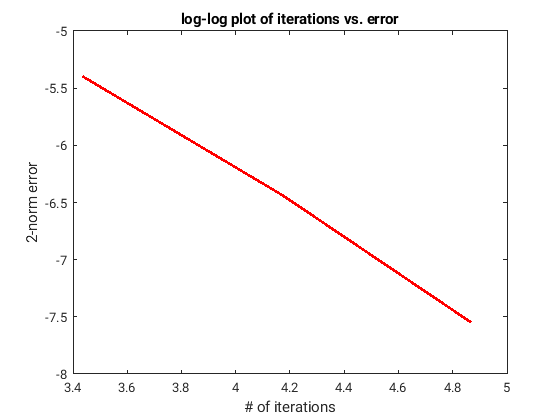

plot(log(iter), log(e), 'r-', 'LineWidth', 2)
xlabel('# of iterations')
ylabel('2-norm error')
title('log-log plot of iterations vs. error')

`Near-optimal `$\omega$ `= 1.61 (n = 16),  1.82 (n = 32), 1.91 (n = 64) (To minimise number of iterations required)`

`Comments on convergence:`` As the problem size (n) increases, we note that the number of iterations required to achieve the same amount of tolerance increases as well. However, with the correct weights (GS and SOR), the error decreases with increasing problem size. The slope of the iteration vs. error log-log plot is 0.5. This is not as good as observed in Q1, particularly because the tridiagonal solver generates an exact solution, whereas these iterative methods, generate approximate solutions. We have an efficient algorithm for solving tridiagonal systems. In such a case, using these iterative methods is counter-productive. However, in case there is no exact solver for a matrix system, these iterative methods can be used, which do converge and produce correct results with small errors.  `

## `Function Definitions`

function x = tridiagsolver(A, d)
    % tridiagonal solver (A is tri-diagonal)
    
    % size of matrix
    n = size(A, 1);
    
    % upper diagonal of A = b(i) = A(i, i+1)
    % lower diagonal of A = c(i) = A(i+1, i)
    % diagonal of A = a(i) = A(i, i)
    
    % compute LU decomposition of A
    m = zeros(n, 1);
    l = zeros(n-1, 1);
    m(1) = A(1, 1);
    for j = 1:n-1
        l(j) = A(j+1, j)/m(j);
        m(j+1) = A(j+1, j+1) - l(j)*A(j, j+1);
    end
    
    % forward substitution on Ly = d
    y = zeros(n, 1);
    y(1) = d(1);
    for j = 2:n
        y(j) = d(j) - l(j-1)*y(j-1);
    end
    
    % backward substitution on Ux = y
    x = zeros(n, 1);
    x(n) = y(n)/m(n);
    for j = n-1:-1:1
        x(j) = (y(j) - A(j, j+1)*x(j+1))/m(j);
    end
end